# Further Exploration 1: Develop a Model Programmatically

The Regression Learner app provides an easy-to-use interface to evaluate multiple models. For added customization, you can develop your models programmatically in MATLAB.

- Repeat the steps from 1.a. through 4.a. of [Machine Learning for Regression: Part 2](matlab:open('LoadForecastRegression.mlx')) in the **Output inline** mode  . Doing this will allow you to understand and reuse parts of the code for preprocessing and feature extraction.

- Fit a linear regression model to the training data TrainNYC. See [`fitlm`](https://www.mathworks.com/help/stats/fitlm.html). Use the [`predict`](https://www.mathworks.com/help/stats/linearmodel.predict.html) function to apply the model to test data TestNYC.

- Similar to step 4.d. in  [Machine Learning for Regression: Part 2](matlab:open('LoadForecastRegression.mlx')), evaluate the model against actual load values for test data and plot the results.

Repeat this process, replacing the linear regression model in step 2 with

- a stepwise regression model (see [`stepwiselm`](https://www.mathworks.com/help/stats/stepwiselm.html)) 

- an ensemble of regression trees (see [`TreeBagger`](https://www.mathworks.com/help/stats/treebagger.html))

In each of the above cases, read the documentation to set the different options and parameters available for the model.

Compare the models.

- Can you tell which model is the best?

- Are there periods where one model performs better than other models?

## **Sample starter solution for **`fitlm`

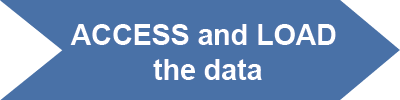

% Load the electricity load data.
load nyiso_cleaned.mat nyiso;

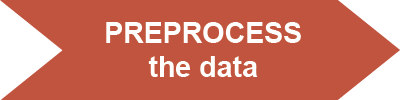

% Extract the data for New York City.
NYCData = nyiso(:,"N_Y_C_");

% Change the table column name to be more general.
NYCData.Properties.VariableNames = "Load"

% Retime the time series to an hourly granularity.
NYCHourly = retime(NYCData,"hourly");

% Converr the data to a table for extracting features.
NYCHourly = timetable2table(NYCHourly);
NYCHourly(end,:) = []

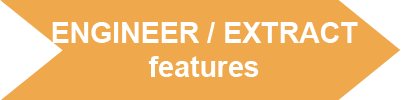

% Extract lag features.
PreviousLoads = lagmatrix(NYCHourly.Load,[1 24 168]);
NYCHourly.PreviousLoad = PreviousLoads(:,1);
NYCHourly.PreviousDayLoad = PreviousLoads(:,2);
NYCHourly.PreviousWeekLoad = PreviousLoads(:,3)

% Extract data and time features.
dates = NYCHourly.Date;
NYCHourly.DayOfWeek = weekday(dates);
NYCHourly.Hour = hour(dates);
NYCHourly.Month = month(dates);
NYCHourly.Year = year(dates);

% Transform the cyclical time features into sine and cosine components
NYCHourly.HourX = sin(2*pi*NYCHourly.Hour/24);
NYCHourly.HourY = cos(2*pi*NYCHourly.Hour/24);

% Convert the months to sin and cos features
NYCHourly.MonthX = sin(2*pi*NYCHourly.Month/12);
NYCHourly.MonthY = cos(2*pi*NYCHourly.Month/12);

% Convert the days of week to sin and cos features
NYCHourly.DayOfWeekX =sin(2*pi*NYCHourly.DayOfWeek/7);
NYCHourly.DayOfWeekY = cos(2*pi*NYCHourly.DayOfWeek/7);

% Delete the old features
NYCHourly.Hour = [];
NYCHourly.Month = [];
NYCHourly.DayOfWeek = [];

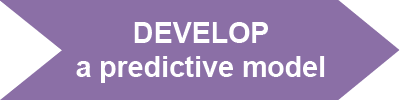

% Split the date into training and test sets.
TrainStart = "2017-May-08 00:00";
TrainEnd = "2019-Dec-31 23:00";
idxtrain = isbetween(NYCHourly.Date, datetime(TrainStart,"TimeZone","America/New_York"), ...
                                     datetime(TrainEnd,"TimeZone","America/New_York")); 
idxtest = NYCHourly.Date > datetime(TrainEnd,"TimeZone","America/New_York");
TrainNYC = NYCHourly(idxtrain,2:end)
TestNYC = NYCHourly(idxtest,2:end)

% Fit a linear model to predict load.
mdlLM = fitlm(TrainNYC,"ResponseVar","Load");

% Apply the model to predict output for test data.
yPredTest = predict(mdlLM,TestNYC(:,2:end));

% Evaluate the predictions against actual load values.
PlotDataLM = table2timetable(NYCHourly(idxtest,:));
PlotDataLM.Pred = yPredTest;
PlotDataLM.Error = (PlotDataLM.Pred - PlotDataLM.Load);
rmseLM = sqrt(mean((PlotDataLM.Error).^2));

% Plot the predicted versus actual load along with the errors.
PlotVars = {["Load" "Pred"], "Error"};
figure
stackedplot(PlotDataLM,PlotVars, ...
    "Title", ["Comparison of actual and predicted load"; "Test RMSE= " + num2str(rmseLM)]);